# **Upload Data**

To change from R to matlab, you must load the Dataset "Needs" and rebuild the two training and test datasets.

clear all
clc
load('TrainNeeds.mat');
load('TestNeeds.mat');
load('Needs')

Dataor=Needs;

# **Dataset modified**

We only select the interesting features according to the results we obtained applying a logistic regression (see code on R).

In particular, the most relevant features are Age, Family, Financial education, Income and Wealth.

In this case we use **rescaled and trasformed **dataset**. **We trasform the variables Income and Wealth following power and logaritmic laws.

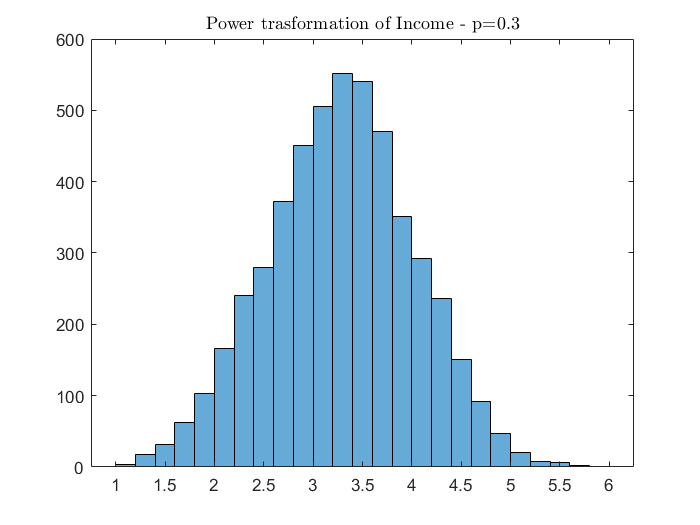

p = 0.3;
PowerIncome = Dataor.Income.^p;
figure
histogram(Dataor.Income.^p);
title('Power trasformation of Income - p=0.3',"Interpreter",'latex')

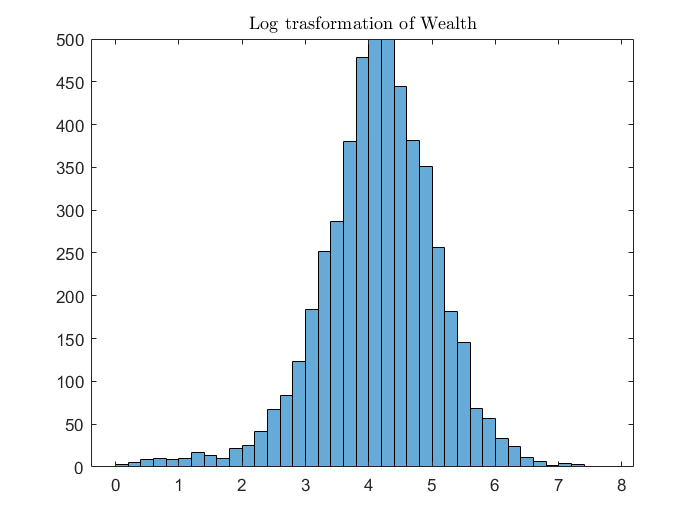

% Log trasformation of Wealth
figure
logWealth = log(Dataor.Wealth);
histogram(log(Dataor.Wealth))
title('Log trasformation of Wealth',"Interpreter",'latex')

Therefore, we divide properly the datadet, partitioning it in training and test part.

% for reproducibility
rng('default');

% Creation of Dataorset following R hints 
DataorSmall = [rescale(Dataor.Age) rescale(Dataor.FamilyMembers) rescale(Dataor.FinancialEducation)...
     rescale(PowerIncome) rescale(logWealth)];

Dataornames = {'Age', 'Family', 'FinEdu', 'Income', 'Wealth'};

Train = DataorSmall(TrainNeeds1.Numberinizialdataset, :);
Test = DataorSmall(TestNeeds.Numberinizialdataset, :);


% Final Train set table
TrainRescale = table(Train(:,1),Train(:,2),Train(:,3),Train(:,4),Train(:,5),'VariableNames',Dataornames);
% Final Test set table
TestRescale = table(Test(:,1),Test(:,2),Test(:,3),Test(:,4),Test(:,5),'VariableNames',Dataornames);
% Responses Train
AccumulationInvestment_Train = TrainNeeds1.AccumulationInvestment;

% Responses Test
AccumulationInvestment_Test = TestNeeds.AccumulationInvestment;


## **Accumulation Investment classifier**

It is a **ensemble tree (Bagged).**

Ensemble tree is combining two or more trees together and then synthesize the result into single score. Single model can have biases, high variability or inaccuracies that affect the reliability of its analytical findings, so ensemble model can be used to improve all of this.

It is certainly less risky to propose Accumulation investments, for this reason the cost of miscassification are really bold. This has been done to fully follow the main objective: propose affordable products for company to the customer.

- error 1 (true class=0 vs predicted class=1)  -> misclassification cost= 1

- error 2 (true class=1 vs predicted class=0)  -> misclassification cost= 2

template = templateTree('MaxNumSplits', 3999);
response = AccumulationInvestment_Train;
rng('default')

classificationEnsemble = fitcensemble(...
    TrainRescale, ...
    response, ...
    'Method', 'Bag', ...
    'Learners', template, ...
    'ClassNames', categorical({'0'; '1'}),...
    'Cost', [0 1; 2 0],...
    'CrossVal','off')

classificationEnsemble =   ClassificationBaggedEnsemble
           PredictorNames: {'Age'  'Family'  'FinEdu'  'Income'  'Wealth'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1]
           ScoreTransform: 'none'
          NumObservations: 4000
               NumTrained: 100
                   Method: 'Bag'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: []
       FitInfoDescription: 'None'
                FResample: 1
                  Replace: 1
         UseObsForLearner: [4000×100 logical]

  Properties, Methods


**PREDICTION ON TEST SET**

% Prediction on test set
[labelsA,scores] = predict(classificationEnsemble,TestRescale);
tabulate(labelsA)

  Value    Count   Percent
      0      478     47.80%
      1      522     52.20%


**Evaluation Accumulation classifier**

%% Evaluation Accumulation classifier
tp = sum((labelsA == '1') & (AccumulationInvestment_Test==1));
fp = sum((labelsA == '1') & (AccumulationInvestment_Test==0));
fn = sum((labelsA == '0') & (AccumulationInvestment_Test==1));

% Precision computation
Precision = tp / (tp + fp)

Precision = 0.8161

% recall computation
Recall = tp / (tp + fn)

Recall = 0.7933

% F1 score
F1 = 2 * Precision * Recall / (Precision + Recall)

F1 = 0.8045

beta=1.5;
FBeta= ((1+beta^2) *(Precision * Recall)) / (beta^2*Precision + Recall)

FBeta = 0.8002

**Confusion matrix**

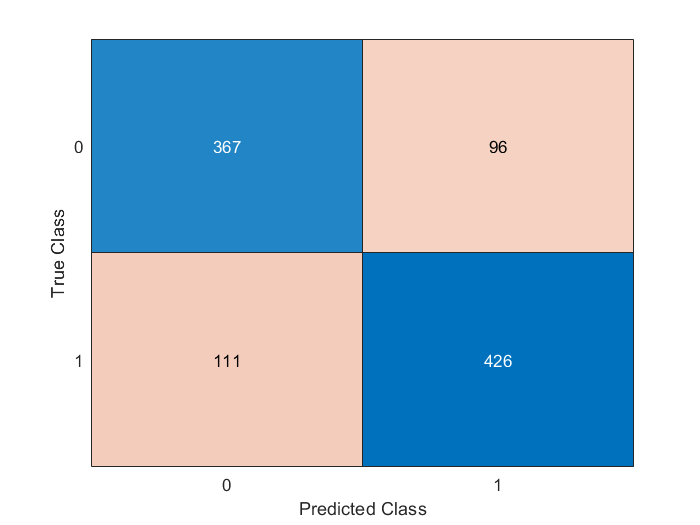

confusionchart(AccumulationInvestment_Test, double(labelsA)-1)